# Electricity Consumption

Instructions are in the task pane to the left. Complete and submit each task one at a time. 

This code loads the electricity usage data. 

electricityData = readtable("./data/electricityData.csv");
time = electricityData.time;
usage = electricityData.usage;
elecFun = @(x) -0.000537*x.^3 + 0.00926*x.^2 + 0.1526.*x + 7.418 - 10; 

## Task 1

The file electricityData.mat contains two variables: `time` and `usage`, and has been loaded into your workspace.

variable `time`  is given in years since 1991, and the variable `usage` contains the electricity usage data in 10^9 kilowatt hours per day at each time in `time`.

It can be easier to visualize when `usage` reaches `10` by plotting `usage` `-` `10` versus `time` and looking for roots.

plot(time, usage-10)

## Task 2

Finding when the long term trend reaches 10×10^9 kWh/day is equivalent to solving the equation −0.000537*x^*3+0.00926*x^*2+0.1526*x*+7.418=10

The function handle `elecFun` contains the root finding form of this equation.

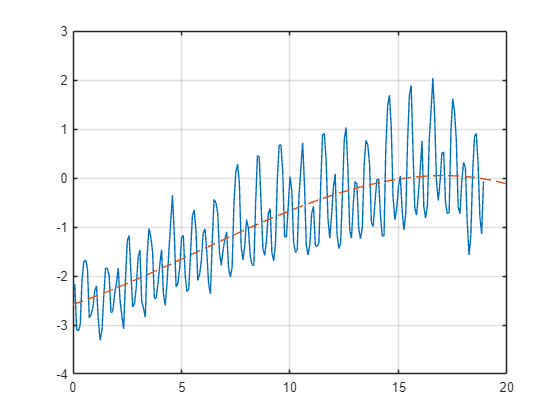

hold on
fplot(elecFun, [0 20], "--")
hold off
grid on

## Task 3

x0 = [10 17]

x0 =     10    17


## Task 4

x = fzero(elecFun, x0)

x = 15.3491